clear;clc
[x,fs] = audioread('C_01_02.wav');
%sound(x, fs)
t = ((0:length(x)-1)/fs)';
LPF_cuttoff = 50;
Ts = 1/fs

Ts = 6.2500e-05

%noisy signal
SNR = -5;
sig = repmat(x, 1, 10);
whitenoise = 1-2*rand(length(x), 1);
[Pxx, f] = pwelch(sig, 512, [], 512, fs);
b = fir2(3000, f/(fs/2), sqrt(Pxx/max(Pxx)));
SSN = filter(b, 1, whitenoise);
E_noise = norm(x)^2/ 10^(SNR/10);
SSN = SSN/norm(SSN)*sqrt(E_noise);
SNR_verfied = 20*log10(norm(x)/norm(SSN))

SNR_verfied = -5

sig = x + SSN;
sig_norm = sig/norm(sig)*norm(x);

% Verifying LPF filter cutoff 50Hz
[b, a] = butter(2, LPF_cuttoff/(fs/2))

b = 1.0e-03 *

    0.0951    0.1901    0.0951


a =     1.0000   -1.9722    0.9726


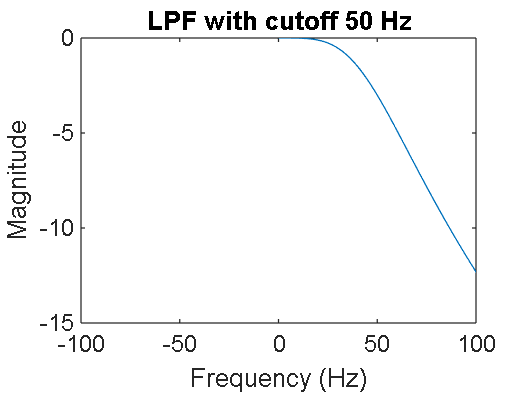

[H, w] = freqz(b, a , fs, fs);
figure;
plot(w, 20*log10(abs(H)));
xlim([-100, 100]);
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title("LPF with cutoff 50 Hz")



%plot
wstep = 2*pi/length(x)*fs

wstep = 3.3922

w = ((0:length(x)-1)-length(x)/2)*wstep;
f = w*fs/(2*pi)/1e6 %in MHz

f =  -128.0000 -127.9914 -127.9827 -127.9741 -127.9654 -127.9568 -127.9482 -127.9395 -127.9309 -127.9223 -127.9136 -127.9050 -127.8963 -127.8877 -127.8791 -127.8704 -127.8618 -127.8532 -127.8445 -127.8359 -127.8272 -127.8186 -127.8100 -127.8013 -127.7927 -127.7840 -127.7754 -127.7668 -127.7581 -127.7495 -127.7409 -127.7322 -127.7236 -127.7149 -127.7063 -127.6977 -127.6890 -127.6804 -127.6718 -127.6631 -127.6545 -127.6458 -127.6372 -127.6286 -127.6199 -127.6113 -127.6026 -127.5940 -127.5854 -127.5767


X = fftshift(fft(x)*Ts)

X =    0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i


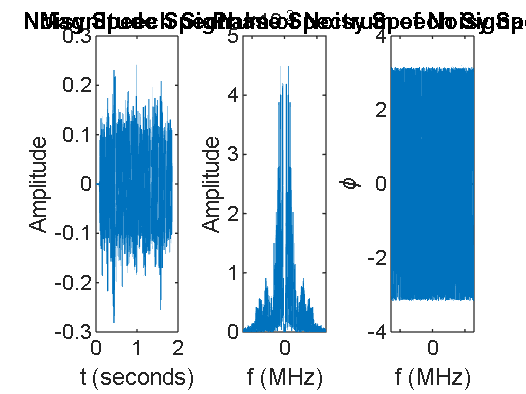

figure;
subplot(1, 3, 1), plot(t, sig_norm);
xlabel('t (seconds)');
ylabel('Amplitude')
title('Noisy Speech Signal')
subplot(1, 3, 2), plot(f, abs(X));
xlabel('f (MHz)');
ylabel('Amplitude')
title('Magnitude Spectrum of Noisy Speech Signal')
subplot(1, 3, 3), plot(f, angle(X));
xlabel('f (MHz)');
ylabel('\phi')
title('Phase Spectrum of Noisy Speech Signal')

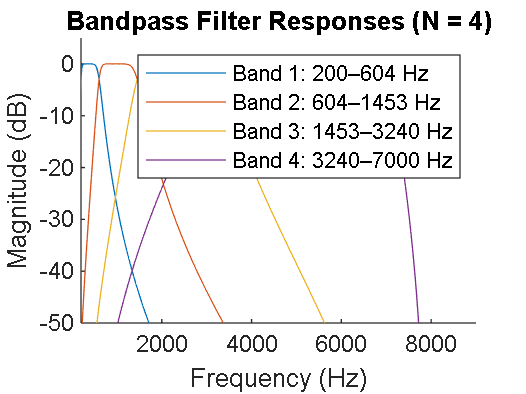

audiowrite('Noisy Speech.mp3', sig_norm, fs)

function result = tone_vocoder_noise(N, x, fs)
LPF_cuttoff = 50;
Ts = 1/fs;
t = ((0:length(x)-1)/fs)';
syms d
eq = 200==165.4 * (10^(0.06 *d)-1);
eq2 = 7000==165.4*(10^(0.06*d)-1);
d_200 = solve(eq, d);
d_7000 = solve(eq2, d);
delta_d = (d_7000 - d_200)/N;
list_cutoff= zeros(1, N+1);
list_cutoff(1) = 200;
for i = 1:N-1
    d_i = d_200 + delta_d * i;
    f_i = 165.4*(10^(0.06*d_i)-1);
    list_cutoff(i+1) = f_i;
end
list_cutoff(N+1) = 7000;
s_sum = zeros(length(x), 1);


figure;
hold on
axis([200 9000 -50 5]);  
for i = 1:N
    f1 = list_cutoff(i);
    f2 =list_cutoff(i+1);
    [b1, a1] = butter(4, [f1 f2]/(fs/2));

    %Bandpass Filter verification 
    [H, w] = freqz(b1, a1, 1024, fs);
    plot(w, 20*log10(abs(H)));

    y = filter(b1, a1, x);
    y_full = abs(y);
    [b2, a2] = butter(2, LPF_cuttoff/(fs/2));
    f_center = (f1 + f2)/2;
    sinwave = sin(2*pi*f_center*t);
    y_rect = filter(b2, a2, y_full);
    y_sin = y_rect.*sinwave;
    s_sum = s_sum + y_sin;
end

xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
if N == 4
    title('Bandpass Filter Responses (N = 4)');
elseif N == 8
    title('Bandpass Filter Responses (N = 8)');
elseif N == 16
    title('Bandpass Filter Responses (N = 16)');
else 
    title('Bandpass Filter Responses (N = 32)');
end
for i = 1:N
    legendStrings{i} = sprintf('Band %d: %.0f–%.0f Hz', i, list_cutoff(i), list_cutoff(i+1));
end
legend(legendStrings);

result = s_sum/norm(s_sum) * norm(x);
end

function result = get_envelope(y, LPF_cuttoff, fs)
y_rect = abs(y);
[b, a] = butter(2, LPF_cuttoff/(fs/2));
result = filter(b, a, y_rect);
end

%Waveform
y_N1 = tone_vocoder_noise(4, sig_norm, fs);

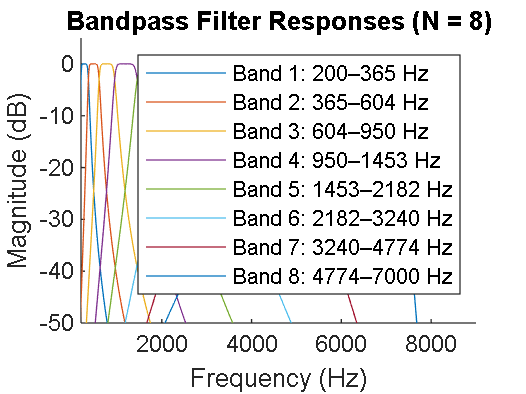

y_N2 = tone_vocoder_noise(8, sig_norm, fs);

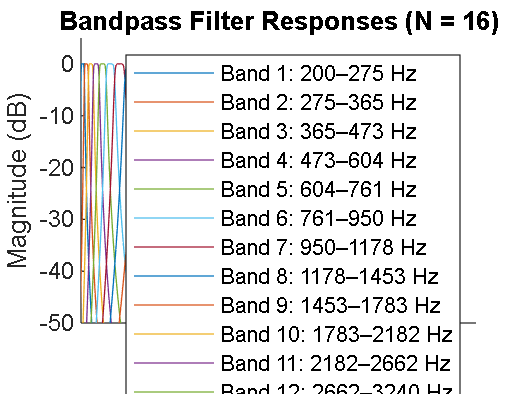

y_N3 = tone_vocoder_noise(16, sig_norm, fs);

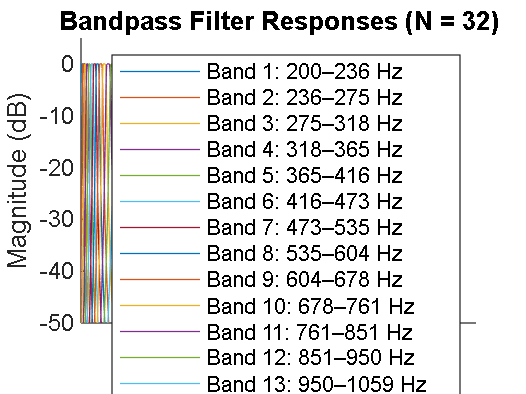

y_N4 = tone_vocoder_noise(32, sig_norm, fs);

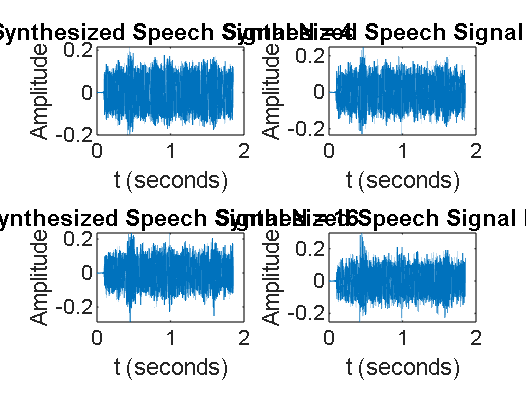


%sound(y_N1, fs)
%sound (y_N2, fs)
%sound (y_N3, fs)
%sound (y_N4, fs)

figure;
subplot(2,2,1), plot(t, y_N1)
xlabel('t (seconds)');
ylabel('Amplitude')
title('Synthesized Speech Signal N = 4')
subplot(2, 2, 2), plot(t, y_N2)
xlabel('t (seconds)');
ylabel('Amplitude')
title('Synthesized Speech Signal N = 8')
subplot(2, 2, 3), plot(t, y_N3)
xlabel('t (seconds)');
ylabel('Amplitude')
title('Synthesized Speech Signal N = 16')
subplot(2, 2, 4), plot(t, y_N4)
xlabel('t (seconds)');
ylabel('Amplitude')
title('Synthesized Speech Signal N = 32')



%Magnitude
wstep = 2*pi/length(y_N1)*fs

wstep = 3.3922

w = ((0:length(y_N1)-1)-length(y_N1)/2)*wstep;
f = w*fs/(2*pi)/1e6 %in MHz

f =  -128.0000 -127.9914 -127.9827 -127.9741 -127.9654 -127.9568 -127.9482 -127.9395 -127.9309 -127.9223 -127.9136 -127.9050 -127.8963 -127.8877 -127.8791 -127.8704 -127.8618 -127.8532 -127.8445 -127.8359 -127.8272 -127.8186 -127.8100 -127.8013 -127.7927 -127.7840 -127.7754 -127.7668 -127.7581 -127.7495 -127.7409 -127.7322 -127.7236 -127.7149 -127.7063 -127.6977 -127.6890 -127.6804 -127.6718 -127.6631 -127.6545 -127.6458 -127.6372 -127.6286 -127.6199 -127.6113 -127.6026 -127.5940 -127.5854 -127.5767


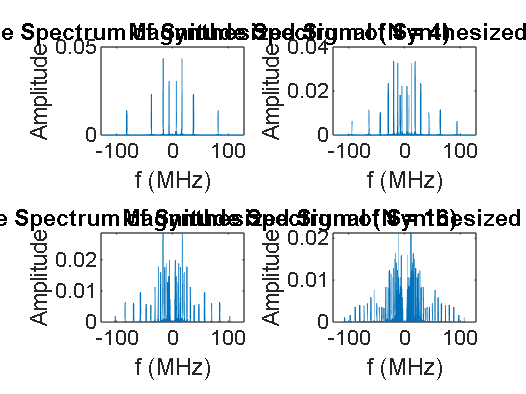

Y_N1 = fftshift(fft(y_N1)*(1/fs));
Y_N2 = fftshift(fft(y_N2)*(1/fs));
Y_N3 = fftshift(fft(y_N3)*(1/fs));
Y_N4 = fftshift(fft(y_N4)*(1/fs));

figure; 
subplot(2, 2, 1), plot(f, abs(Y_N1))
xlabel('f (MHz)');
ylabel('Amplitude')
title('Magnitude Spectrum of Synthesized Signal (N = 4)')
subplot(2, 2, 2), plot(f, abs(Y_N2))
xlabel('f (MHz)');
ylabel('Amplitude')
title('Magnitude Spectrum of Synthesized Signal (N = 8)')
subplot(2, 2, 3), plot(f, abs(Y_N3))
xlabel('f (MHz)');
ylabel('Amplitude')
title('Magnitude Spectrum of Synthesized Signal (N = 16)')
subplot(2, 2, 4), plot(f, abs(Y_N4))
xlabel('f (MHz)');
ylabel('Amplitude')
title('Magnitude Spectrum of Synthesized Signal (N = 32)')

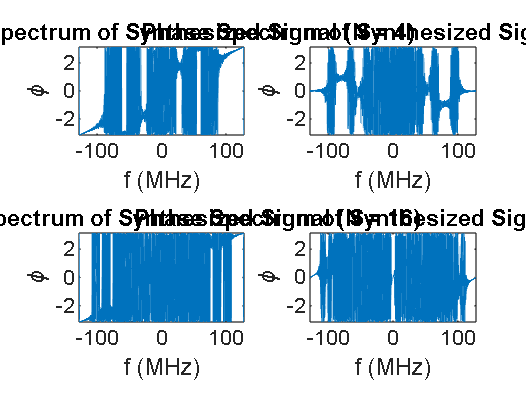


%Phase
figure;
subplot(2, 2, 1), plot(f, angle(Y_N1))
xlabel('f (MHz)');
ylabel('\phi')
title('Phase Spectrum of Synthesized Signal (N = 4)')
subplot(2, 2, 2), plot(f, angle(Y_N2))
xlabel('f (MHz)');
ylabel('\phi')
title('Phase Spectrum of Synthesized Signal (N = 8)')
subplot(2, 2, 3), plot(f, angle(Y_N3))
xlabel('f (MHz)');
ylabel('\phi')
title('Phase Spectrum of Synthesized Signal (N = 16)')
subplot(2, 2, 4), plot(f, angle(Y_N4))
xlabel('f (MHz)');
ylabel('\phi')
title('Phase Spectrum of Synthesized Signal (N = 32)')

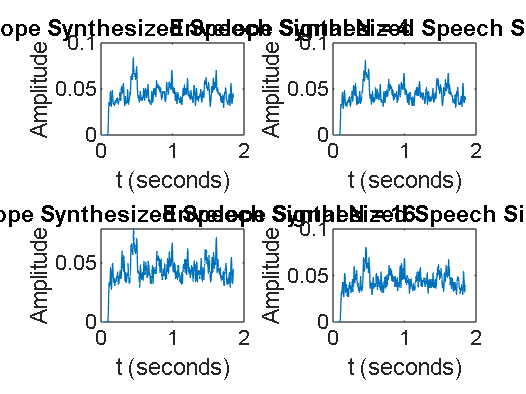


%Envelope
y1_env = get_envelope(y_N1, LPF_cuttoff, fs);
y2_env = get_envelope(y_N2, LPF_cuttoff, fs);
y3_env = get_envelope(y_N3, LPF_cuttoff, fs);
y4_env = get_envelope(y_N4, LPF_cuttoff, fs);
figure; 
subplot(2, 2, 1), plot(t, y1_env);
xlabel('t (seconds)');
ylabel('Amplitude')
title('Envelope Synthesized Speech Signal N = 4')
subplot(2, 2, 2), plot(t, y2_env);
xlabel('t (seconds)');
ylabel('Amplitude')
title('Envelope Synthesized Speech Signal N = 8')
subplot(2, 2, 3), plot(t, y3_env);
xlabel('t (seconds)');
ylabel('Amplitude')
title('Envelope Synthesized Speech Signal N = 16')
subplot(2, 2, 4), plot(t, y4_env);
xlabel('t (seconds)');
ylabel('Amplitude')
title('Envelope Synthesized Speech Signal N = 32')


%Energy Normalization Verification
E_ori = (norm(x)).^2

E_ori = 87.0316

E_N1 = (norm(y_N1)).^2

E_N1 = 87.0316

E_N2 = (norm(y_N2)).^2

E_N2 = 87.0316

E_N3 = (norm(y_N3)).^2

E_N3 = 87.0316

E_N4 = (norm(y_N4)).^2

E_N4 = 87.0316

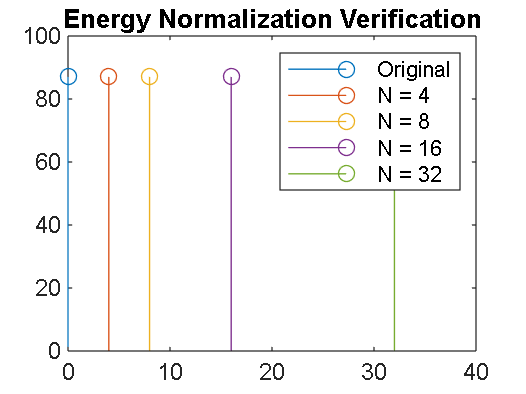


figure;
xlim([-6.2 37.8])
ylim([4 114])
stem(0, E_ori);
hold on
stem(4, E_N1);
hold on
stem(8, E_N2);
hold on
stem(16, E_N3);
hold on
stem(32, E_N4);
legend('Original', 'N = 4', 'N = 8', 'N = 16', 'N = 32')
title('Energy Normalization Verification')


audiowrite('Synthesized N1.mp3', y_N1, fs)
audiowrite('Synthesized N2.mp3', y_N2, fs)
audiowrite('Synthesized N3.mp3', y_N3, fs)
audiowrite('Synthesized N4.mp3', y_N4, fs)



